### Global settings:

Tire data scaling factor:

scalefactor = 1;

Load and SA step size:

d_SA = 0.1;
d_load = 20;
SAbounds = [-15 15];
loadbounds = [-1200 0];

Load tire data:

% Change this path to wherever your tire data is
load('Tire model/TTC data files/B1965run2.mat')
n_data = size(ET,1);

Group camber data:

% Change these indices if using a different tire data file
[camber_lb,camber_ub] = groupdata(IA(1250:19984),3,0.5,1249);

Declare variables:

C = zeros(10,6);
index_order = [3 5 2 1 4];
load_y = (loadbounds(1):d_load:loadbounds(2))';
n_load = length(load_y);
SA_x = SAbounds(1):d_SA:SAbounds(2);
n_SA = length(SA_x);
lat_coeff_inc = zeros(n_load,n_SA,3);
lat_coeff_dec = zeros(n_load,n_SA,3);
poly_coeff_inc = zeros(3,n_SA,3);
poly_coeff_dec = zeros(3,n_SA,3);

### 1st camber group (0 deg)

[load_lb,load_ub] = groupdata(FZ(camber_lb(1):camber_ub(1)),5,100,camber_lb(1)-1);

Find the average value in each load group:

loads = [
    mean(FZ(load_lb(1):load_ub(1))) ...
    mean(FZ(load_lb(2):load_ub(2))) ...
    mean(FZ(load_lb(3):load_ub(3))) ...
    mean(FZ(load_lb(4):load_ub(4))) ...
    mean(FZ(load_lb(5):load_ub(5))) ...
    ];
loads = loads(index_order);

Group data:


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


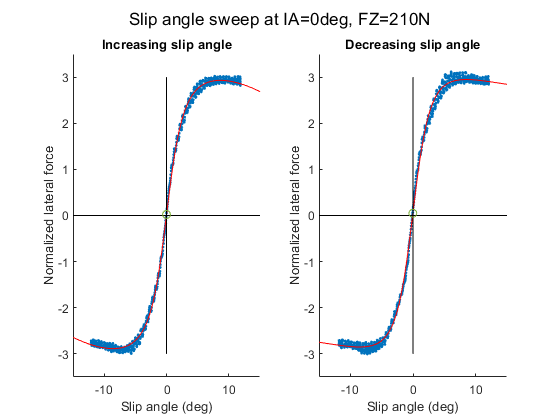


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>



Solver stopped prematurely.

lsqcurvefit stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 3.000000e+03.



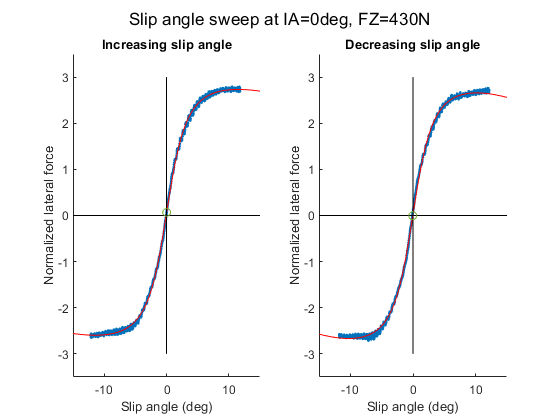


Solver stopped prematurely.

lsqcurvefit stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 3.000000e+03.




Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


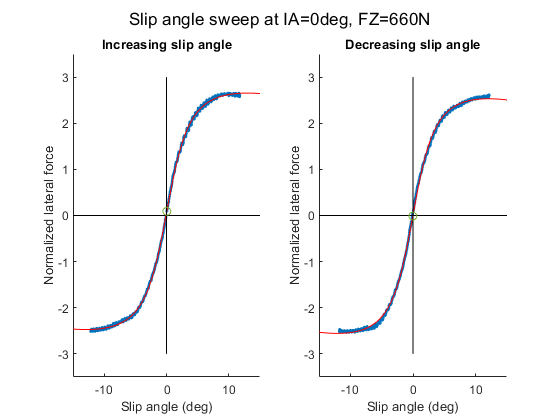


Solver stopped prematurely.

lsqcurvefit stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 3.000000e+03.




Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


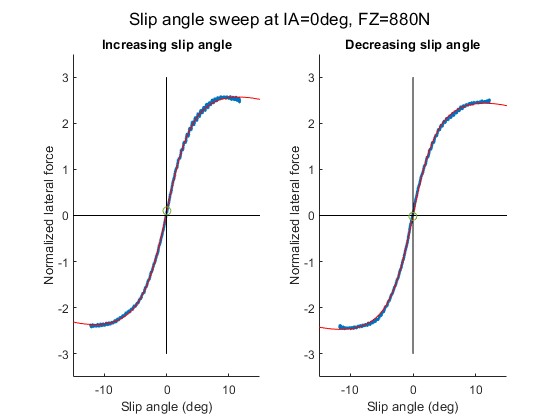


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>



Solver stopped prematurely.

lsqcurvefit stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 3.000000e+03.



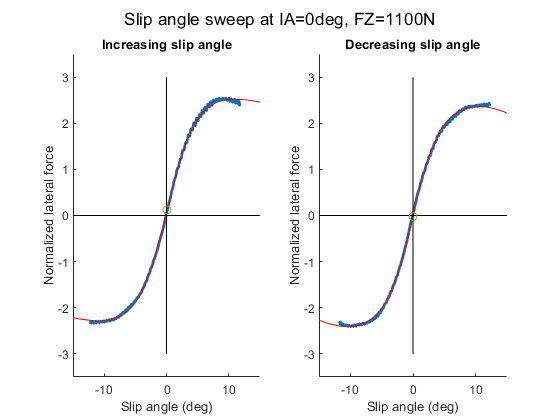

for i = 1:size(load_lb,1)
   index = index_order(i);
   [SA_lb,SA_ub] = groupdata(SA(load_lb(index):load_ub(index)),3,0.19,load_lb(index)-1);
   alpha = {[SA(SA_lb(1):SA_ub(1));SA(SA_lb(3):SA_ub(3))], SA(SA_lb(2):SA_ub(2))};
   mu_y = {[NFY(SA_lb(1):SA_ub(1));NFY(SA_lb(3):SA_ub(3))], NFY(SA_lb(2):SA_ub(2))};
   C(2*i-1:2*i,:) = fit(alpha, mu_y, scalefactor, 0, loads(i));
end

Print out offsets:

disp('Horizontal offsets (deg):')

Horizontal offsets (deg):


disp('    Inc SA    Dec SA')

    Inc SA    Dec SA


disp(rad2deg(atan([C(1,5) C(2,5);C(3,5) C(4,5);C(5,5) C(6,5);C(7,5) C(8,5);C(9,5) C(10,5)])))

    0.0078   -0.0220
    0.0253   -0.0410
    0.0456   -0.0359
    0.0655   -0.0222
    0.0908   -0.0184



disp('Vertical offsets:')

Vertical offsets:


disp('    Inc SA    Dec SA')

    Inc SA    Dec SA


disp([C(1,6) C(2,6);C(3,6) C(4,6);C(5,6) C(6,6);C(7,6) C(8,6);C(9,6) C(10,6)])

    0.0221    0.0486
    0.0686   -0.0043
    0.0906   -0.0125
    0.1017   -0.0182
    0.1192   -0.0221



disp('Camber thrust:')

Camber thrust:


inc_column = [C(1,:); C(3,:); C(5,:); C(7,:); C(9,:)];
dec_column = [C(2,:); C(4,:); C(6,:); C(8,:); C(10,:)];
disp([pacejka(inc_column,0) pacejka(dec_column,0)]);

    0.0135    0.0731
    0.0470    0.0311
    0.0577    0.0140
    0.0609   -0.0040
    0.0696   -0.0116



Stiffness coefficients:

% stiff=zeros(12,1);
% for j=1:12
%     stiff(j)=C(j,3)*C(j,2)*C(j,1)*(1-C(j,4));
% end
% save('lateral_stiffness.mat',"stiff");

Take sample points of each fitted curve (curve is in row):

sample_points = pacejka(C,deg2rad(SA_x));

Split sample points into increasing and decreasing SA:

sample_points_inc = [
    sample_points(1,:); ...
    sample_points(3,:); ...
    sample_points(5,:); ...
    sample_points(7,:); ...
    sample_points(9,:); ...
    ];
sample_points_dec = [
    sample_points(2,:); ...
    sample_points(4,:); ...
    sample_points(6,:); ...
    sample_points(8,:); ...
    sample_points(10,:); ...
    ];

Fit a 4-th order polynomial to each column of points (load sensitivity at each SA):

for i = 1:n_SA
    poly_coeff_inc(:,i,1) = polyfit(loads,sample_points_inc(:,i),2);
end
for i = 1:n_SA
    poly_coeff_dec(:,i,1) = polyfit(loads,sample_points_dec(:,i),2);
end

Populate with extra load values in between the 5 groups given:

for j = 1:n_SA
    lat_coeff_inc(:,j,1) = polyval(poly_coeff_inc(:,j,1),load_y);
end
for j = 1:n_SA
    lat_coeff_dec(:,j,1) = polyval(poly_coeff_dec(:,j,1),load_y);
end

Plot on a heat map:

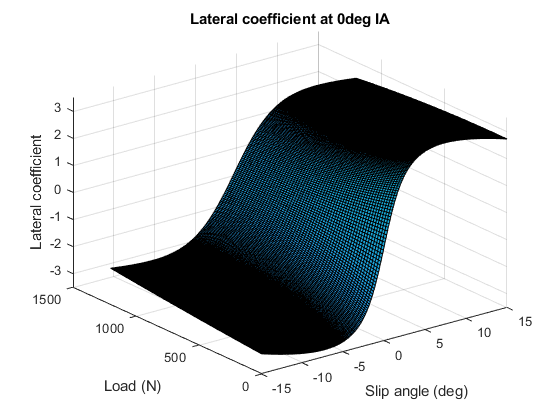

figure
surfl(ones(n_load,1)*SA_x, ...
    -load_y*ones(1,n_SA), ...
    lat_coeff_inc(:,:,1));
xlabel('Slip angle (deg)')
ylabel('Load (N)')
zlabel('Lateral coefficient')
axis([SAbounds(1) SAbounds(2) 0 1500 -3.5 3.5])
title('Lateral coefficient at 0deg IA')

Save data:

temp_inc = lat_coeff_inc;
temp_dec = lat_coeff_dec;
lat_coeff_inc = lat_coeff_inc(:,:,1);
lat_coeff_dec = lat_coeff_dec(:,:,1);
save('Tire model/lateral_force_lut.mat', ...
    'lat_coeff_inc', ...
    'lat_coeff_dec', ...
    'SA_x', ...
    'load_y');
lat_coeff_inc = temp_inc;
lat_coeff_dec = temp_dec;

Save Pacejka coefficients for later use:

C_overall(:,:,1) = C;

### 2nd camber group (2 deg)

[load_lb,load_ub] = groupdata(FZ(camber_lb(2):camber_ub(2)),5,100,camber_lb(2)-1);

Find the average value in each load group:

loads = [
    mean(FZ(load_lb(1):load_ub(1))) ...
    mean(FZ(load_lb(2):load_ub(2))) ...
    mean(FZ(load_lb(3):load_ub(3))) ...
    mean(FZ(load_lb(4):load_ub(4))) ...
    mean(FZ(load_lb(5):load_ub(5))) ...
    ];
loads = loads(index_order);

Group data:


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


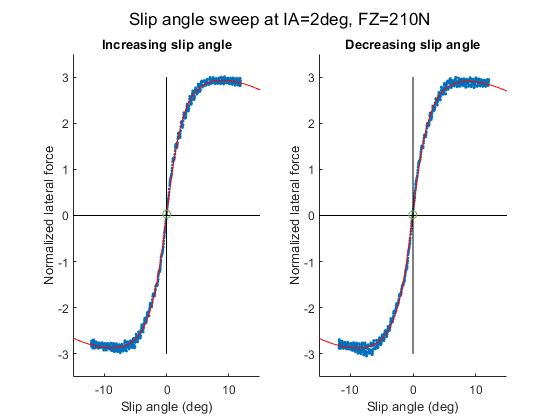


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>



Solver stopped prematurely.

lsqcurvefit stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 3.000000e+03.



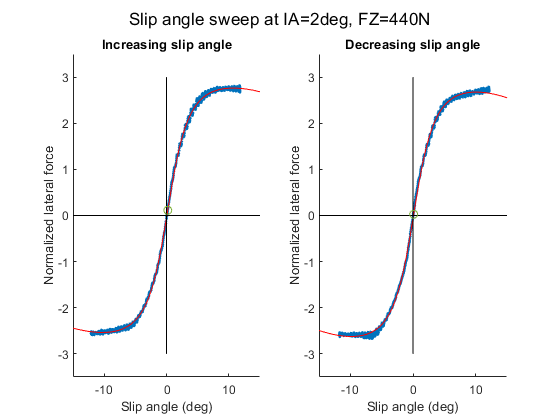


Solver stopped prematurely.

lsqcurvefit stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 3.000000e+03.




Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


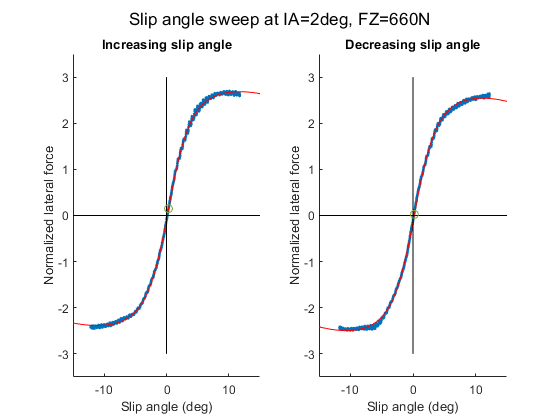


Solver stopped prematurely.

lsqcurvefit stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 3.000000e+03.




Solver stopped prematurely.

lsqcurvefit stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 3.000000e+03.



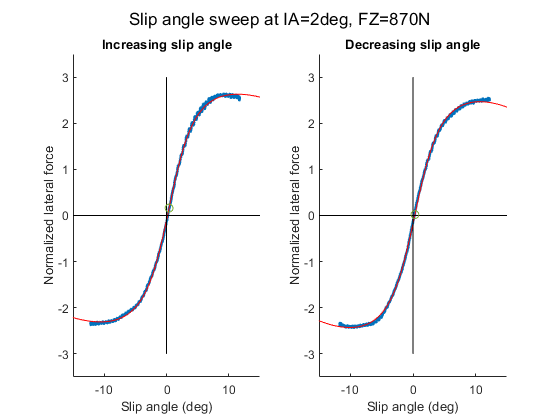


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


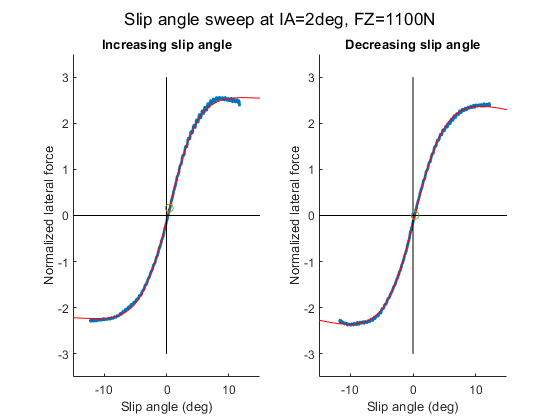

for i=1:size(load_lb,1)
    index = index_order(i);
   [SA_lb,SA_ub] = groupdata(SA(load_lb(index):load_ub(index)),3,0.19,load_lb(index)-1);
   alpha = {[SA(SA_lb(1):SA_ub(1));SA(SA_lb(3):SA_ub(3))], SA(SA_lb(2):SA_ub(2))};
   mu_y = {[NFY(SA_lb(1):SA_ub(1));NFY(SA_lb(3):SA_ub(3))], NFY(SA_lb(2):SA_ub(2))};
   C(2*i-1:2*i,:) = fit(alpha, mu_y, scalefactor, 2, loads(i));
end

Print out offsets:

disp('Horizontal offsets (deg):')

Horizontal offsets (deg):


disp('    Inc SA    Dec SA')

    Inc SA    Dec SA


disp(rad2deg([C(1,5) C(2,5);C(3,5) C(4,5);C(5,5) C(6,5);C(7,5) C(8,5);C(9,5) C(10,5)]))

    0.0305   -0.0381
    0.1986    0.1041
    0.3249    0.2222
    0.4196    0.3031
    0.4621    0.3309



disp('Vertical offsets:')

Vertical offsets:


disp('    Inc SA    Dec SA')

    Inc SA    Dec SA


disp([C(1,6) C(2,6);C(3,6) C(4,6);C(5,6) C(6,6);C(7,6) C(8,6);C(9,6) C(10,6)])

    0.0310    0.0172
    0.1133    0.0261
    0.1489    0.0241
    0.1617    0.0196
    0.1606    0.0030



disp('Camber thrust:')

Camber thrust:


inc_column = [C(1,:); C(3,:); C(5,:); C(7,:); C(9,:)];
dec_column = [C(2,:); C(4,:); C(6,:); C(8,:); C(10,:)];
disp([pacejka(inc_column,0) pacejka(dec_column,0)]);

   -0.0013    0.0584
   -0.0496   -0.0603
   -0.0841   -0.1350
   -0.1055   -0.1717
   -0.0915   -0.1755



Stiffness coefficients:

% stiff=zeros(12,1);
% for j=1:12
%     stiff(j)=C(j,3)*C(j,2)*C(j,1)*(1-C(j,4));
% end
% save('lateral_stiffness.mat',"stiff");

Take sample points of each fitted curve (Pacejka curve is in row):

sample_points = pacejka(C,deg2rad(SA_x));

Split sample points into increasing and decreasing SA:

sample_points_inc = [
    sample_points(1,:); ...
    sample_points(3,:); ...
    sample_points(5,:); ...
    sample_points(7,:); ...
    sample_points(9,:); ...
    ];
sample_points_dec = [
    sample_points(2,:); ...
    sample_points(4,:); ...
    sample_points(6,:); ...
    sample_points(8,:); ...
    sample_points(10,:); ...
    ];

Fit a 4-th order polynomial to each column of points (load sensitivity at each SA):

for i = 1:n_SA
    poly_coeff_inc(:,i,2) = polyfit(loads,sample_points_inc(:,i),2);
end
for i = 1:n_SA
    poly_coeff_dec(:,i,2) = polyfit(loads,sample_points_dec(:,i),2);
end

Populate with extra load values in between the 5 groups given:

for j = 1:n_SA
    lat_coeff_inc(:,j,2) = polyval(poly_coeff_inc(:,j,2),load_y);
end
for j = 1:n_SA
    lat_coeff_dec(:,j,2) = polyval(poly_coeff_dec(:,j,2),load_y);
end

Plot on a heat map:

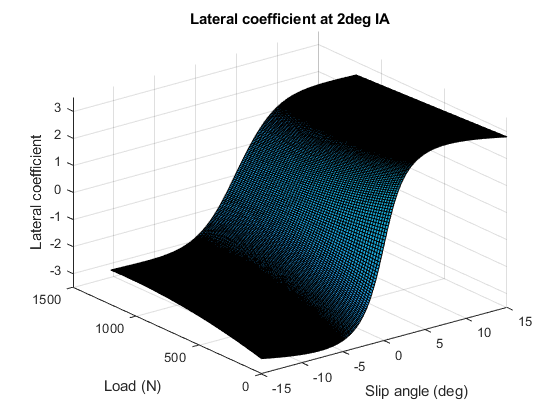

figure
surfl(ones(n_load,1)*SA_x, ...
    -load_y*ones(1,n_SA), ...
    lat_coeff_inc(:,:,2));
xlabel('Slip angle (deg)')
ylabel('Load (N)')
zlabel('Lateral coefficient')
axis([SAbounds(1) SAbounds(2) 0 1500 -3.5 3.5])
title('Lateral coefficient at 2deg IA')

Save Pacejka coefficients for later use:

C_overall(:,:,2) = C;

### 3rd camber group (4 deg)

[load_lb,load_ub] = groupdata(FZ(camber_lb(3):camber_ub(3)),5,100,camber_lb(3)-1);

Find the average value in each load group:

loads = [
    mean(FZ(load_lb(1):load_ub(1))) ...
    mean(FZ(load_lb(2):load_ub(2))) ...
    mean(FZ(load_lb(3):load_ub(3))) ...
    mean(FZ(load_lb(4):load_ub(4))) ...
    mean(FZ(load_lb(5):load_ub(5))) ...
    ];
loads = loads(index_order);

Group data:


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


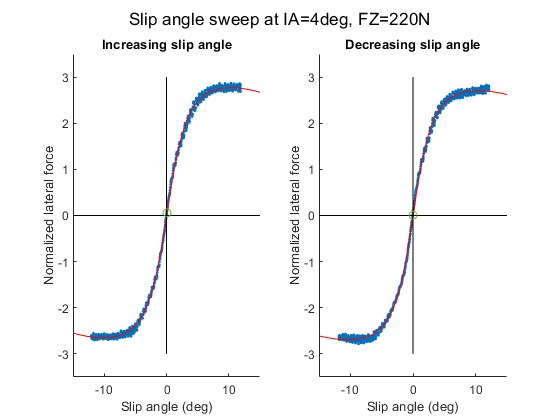


Solver stopped prematurely.

lsqcurvefit stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 3.000000e+03.




Solver stopped prematurely.

lsqcurvefit stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 3.000000e+03.



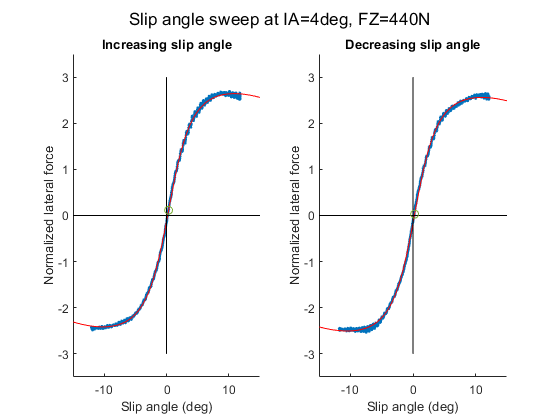


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>



Solver stopped prematurely.

lsqcurvefit stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 3.000000e+03.



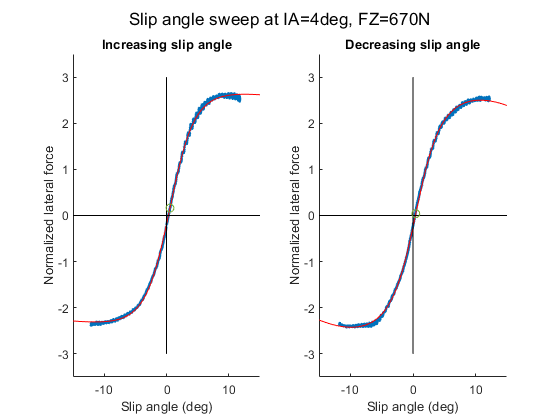


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


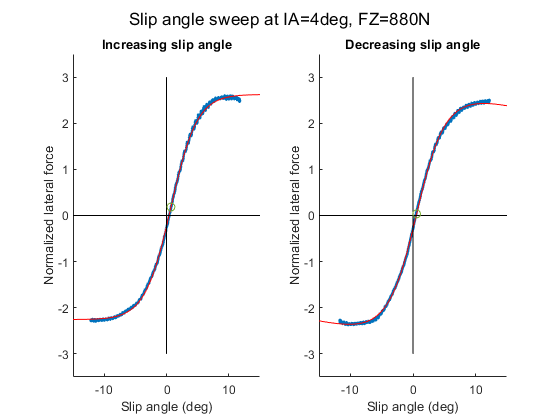


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


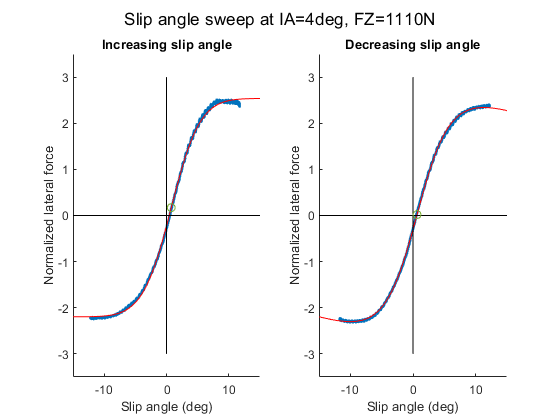

for i=1:size(load_lb,1)
   index = index_order(i);
   [SA_lb,SA_ub] = groupdata(SA(load_lb(index):load_ub(index)),3,0.19,load_lb(index)-1);
   alpha = {[SA(SA_lb(1):SA_ub(1));SA(SA_lb(3):SA_ub(3))], SA(SA_lb(2):SA_ub(2))};
   mu_y = {[NFY(SA_lb(1):SA_ub(1));NFY(SA_lb(3):SA_ub(3))], NFY(SA_lb(2):SA_ub(2))};
   C(2*i-1:2*i,:) = fit(alpha, mu_y, scalefactor, 4, loads(i));
end

Print out offsets:

disp('Horizontal offsets (deg):')

Horizontal offsets (deg):


disp('    Inc SA    Dec SA')

    Inc SA    Dec SA


disp(rad2deg([C(1,5) C(2,5);C(3,5) C(4,5);C(5,5) C(6,5);C(7,5) C(8,5);C(9,5) C(10,5)]))

    0.0930    0.0093
    0.3344    0.2570
    0.5556    0.4435
    0.7146    0.5722
    0.7670    0.6426



disp('Vertical offsets:')

Vertical offsets:


disp('    Inc SA    Dec SA')

    Inc SA    Dec SA


disp([C(1,6) C(2,6);C(3,6) C(4,6);C(5,6) C(6,6);C(7,6) C(8,6);C(9,6) C(10,6)])

    0.0587    0.0060
    0.1135    0.0279
    0.1605    0.0387
    0.1837    0.0353
    0.1703    0.0201



disp('Camber thrust:')

Camber thrust:


inc_column = [C(1,:); C(3,:); C(5,:); C(7,:); C(9,:)];
dec_column = [C(2,:); C(4,:); C(6,:); C(8,:); C(10,:)];
disp([pacejka(inc_column,0) pacejka(dec_column,0)]);

   -0.0217   -0.0023
   -0.1263   -0.1588
   -0.1946   -0.2446
   -0.2308   -0.2866
   -0.2272   -0.2996



Stiffness coefficients:

% stiff=zeros(12,1);
% for j=1:12
%     stiff(j)=C(j,3)*C(j,2)*C(j,1)*(1-C(j,4));
% end
% save('lateral_stiffness.mat',"stiff");

Take sample points of each fitted curve (Pacejka curve is in row):

sample_points = pacejka(C,deg2rad(SA_x));

Split sample points into increasing and decreasing SA:

sample_points_inc = [
    sample_points(1,:); ...
    sample_points(3,:); ...
    sample_points(5,:); ...
    sample_points(7,:); ...
    sample_points(9,:); ...
    ];
sample_points_dec = [
    sample_points(2,:); ...
    sample_points(4,:); ...
    sample_points(6,:); ...
    sample_points(8,:); ...
    sample_points(10,:); ...
    ];

Fit a 4-th order polynomial to each column of points (load sensitivity at each SA):

for i = 1:n_SA
    poly_coeff_inc(:,i,3) = polyfit(loads,sample_points_inc(:,i),2);
end
for i = 1:n_SA
    poly_coeff_dec(:,i,3) = polyfit(loads,sample_points_dec(:,i),2);
end

Populate with extra load values in between the 5 groups given:

for j = 1:n_SA
    lat_coeff_inc(:,j,3) = polyval(poly_coeff_inc(:,j,3),load_y);
end
for j = 1:n_SA
    lat_coeff_dec(:,j,3) = polyval(poly_coeff_dec(:,j,3),load_y);
end

Plot on a heat map:

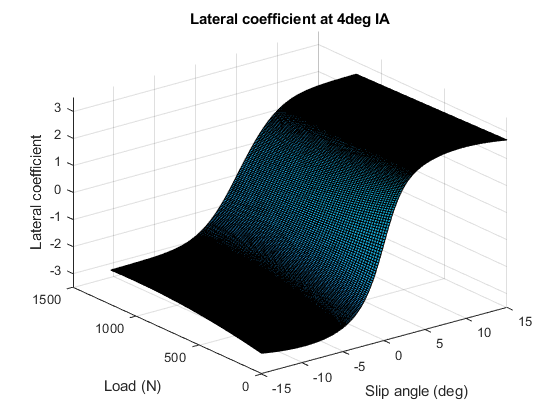

figure
surfl(ones(n_load,1)*SA_x, ...
    -load_y*ones(1,n_SA), ...
    lat_coeff_inc(:,:,3));
xlabel('Slip angle (deg)');
ylabel('Load (N)');
zlabel('Lateral coefficient');
axis([SAbounds(1) SAbounds(2) 0 1500 -3.5 3.5])
title('Lateral coefficient at 4deg IA')

Save Pacejka coefficients for later use:

C_overall(:,:,3) = C;

### Everything together

Plot all of them together:

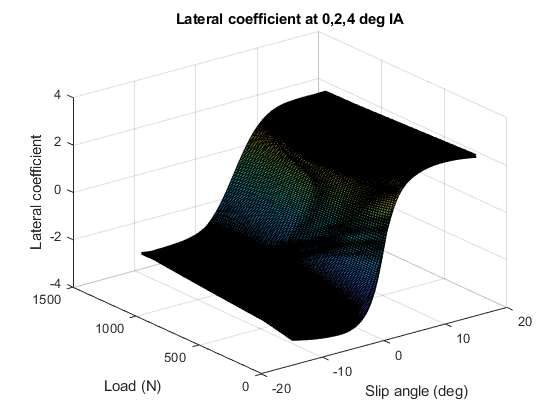

figure
surfl(ones(n_load,1)*SA_x, ...
    -load_y*ones(1,n_SA), ...
    lat_coeff_inc(:,:,1),'light');
xlabel('Slip angle (deg)')
ylabel('Load (N)')
zlabel('Lateral coefficient')
hold on
surfl(ones(n_load,1)*SA_x, ...
    -load_y*ones(1,n_SA), ...
    lat_coeff_inc(:,:,2),'light');
surfl(ones(n_load,1)*SA_x, ...
    -load_y*ones(1,n_SA), ...
    lat_coeff_inc(:,:,3),'light');
title('Lateral coefficient at 0,2,4 deg IA')

Plot camber sensitivity:

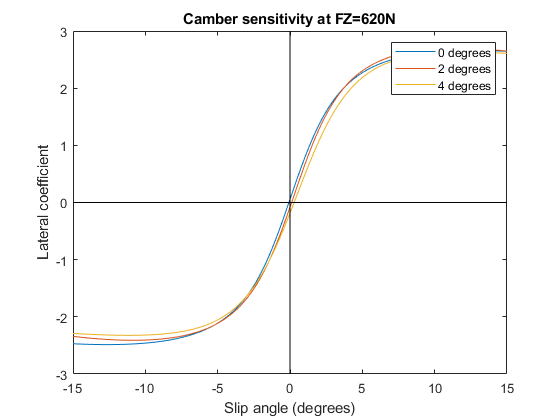

figure;
load_index = 30;
plot(SA_x,lat_coeff_inc(load_index,:,1));
hold on;
plot(SA_x,lat_coeff_inc(load_index,:,2));
plot(SA_x,lat_coeff_inc(load_index,:,3));
xlabel('Slip angle (degrees)');
ylabel('Lateral coefficient');
plot_bounds = [-15 15 -3 3];
plot([plot_bounds(1) plot_bounds(2)], [0 0], 'k') % X-axis
plot([0 0], [plot_bounds(3) plot_bounds(4)], 'k') % Y-axis
axis(plot_bounds)
title(strcat('Camber sensitivity at FZ=', num2str(-load_y(load_index)),'N'));
legend('0 degrees','2 degrees','4 degrees');

Plot effect of camber on load sensitivity:

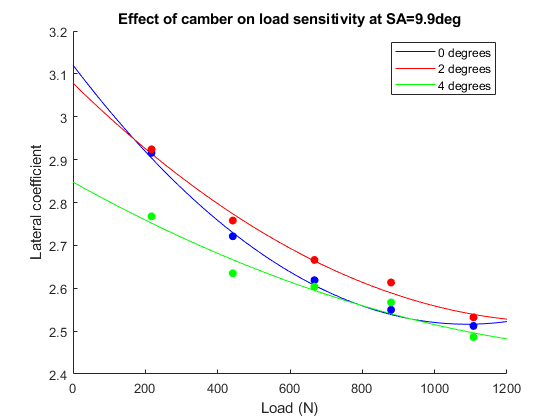

figure;
hold on;
SA_index = 250;
Coeff = zeros(5,6,3);
for page = 1:3
    for row = 1:5
        Coeff(row,:,page) = C_overall(row*2-1,:,page);
    end
end
g_obj(1) = plot(-load_y,lat_coeff_inc(:,SA_index,1),'b');
g_obj(2) = plot(-load_y,lat_coeff_inc(:,SA_index,2),'r');
g_obj(3) = plot(-load_y,lat_coeff_inc(:,SA_index,3),'g');
scatter(-loads,pacejka(Coeff(:,:,1),tan(deg2rad(SA_x(SA_index)))),'b','filled');
scatter(-loads,pacejka(Coeff(:,:,2),tan(deg2rad(SA_x(SA_index)))),'r','filled');
scatter(-loads,pacejka(Coeff(:,:,3),tan(deg2rad(SA_x(SA_index)))),'g','filled');
legend(g_obj, '0 degrees','2 degrees','4 degrees');
xlabel('Load (N)');
ylabel('Lateral coefficient');
title(strcat('Effect of camber on load sensitivity at SA=', num2str(SA_x(SA_index)),'deg'));

%axis([0 1200 0 3])

Delete all relevant variables:

## Functions

Pacejka function:

function y = pacejka(Coeff,sigma)
if size(Coeff,2) ~= 6
    error('Must have 6 coefficients in row')
elseif size(sigma,1) ~= 1
    error('Sigma must be row vector')
end
% Coeff matrix is 6-wide by n_coeff tall
% sigma is n_sigma wide by 1 tall
n_coeff = size(Coeff,1);
n_sigma = size(sigma,2);
% Expand coefficient and sigma matrices
sigma = ones(n_coeff,1)*sigma;
B = Coeff(:,1)*ones(1,n_sigma);
C = Coeff(:,2)*ones(1,n_sigma);
D = Coeff(:,3)*ones(1,n_sigma);
E = Coeff(:,4)*ones(1,n_sigma);
deltaX = Coeff(:,5)*ones(1,n_sigma);
deltaY = Coeff(:,6)*ones(1,n_sigma);
y=D.*sin(C.*atan(B.*(sigma-deltaX)-E.*(B.*(sigma-deltaX)-atan(B.*(sigma-deltaX)))))+deltaY;
end

Fit curve for a single vertical load group:

% alpha_unscaled and mu_unscaled are data arrays, first column is
% increasing SA and second is decreasing SA
function C = fit(alpha_unscaled, mu_unscaled, scalefactor, inc_angle, load_val)

% Scale data
alpha_deg = {alpha_unscaled{1}*scalefactor, alpha_unscaled{2}*scalefactor};
mu = {mu_unscaled{1}*scalefactor, mu_unscaled{2}*scalefactor};

% Convert from column vector to row vector
alpha_deg = {alpha_deg{1}', alpha_deg{2}'};
mu = {mu{1}', mu{2}'};

% Transform alpha -> sigma_y
alpha = {deg2rad(alpha_deg{1}), deg2rad(alpha_deg{2})};
sigma_y = {tan(alpha{1}), tan(alpha{2})};

% Options for fit
lb = -inf*ones(6,1);
ub = inf*ones(6,1);
C0 = [1,1,1,1,0,0];
options = optimoptions('lsqcurvefit', ...
    'MaxFunctionEvaluations',3000, ...
    "Algorithm","levenberg-marquardt");

% Increasing slip angle
% Fit the Pacejka function
[Cfinal_inc,~,~,~,~] = lsqcurvefit(@pacejka,C0,sigma_y{1},mu{1},lb,ub,options);

% Plots
figure
hold off
plot_bounds = [-15 15 -3 3];
subplot(1,2,1);
sgtitle(strcat('Slip angle sweep at IA=',num2str(inc_angle),'deg, FZ=',num2str(round(-load_val,-1)),'N'))
scatter(alpha_deg{1},mu{1},5,'filled')
hold on
x = linspace(-15,15,100);
plot(x,pacejka(Cfinal_inc,tan(deg2rad(x))),'red')
plot([plot_bounds(1) plot_bounds(2)], [0 0], 'k') % X-axis
plot([0 0], [plot_bounds(3) plot_bounds(4)], 'k') % Y-axis
scatter(rad2deg(Cfinal_inc(5)),Cfinal_inc(6))
xlabel('Slip angle (deg)')
ylabel('Normalized lateral force')
title('Increasing slip angle')
axis([-15 15 -3.5 3.5])

% Same thing for decreasing slip angle
% Fit the Pacejka function
[Cfinal_dec,~,~,~,~] = lsqcurvefit(@pacejka,C0,sigma_y{2},mu{2},lb,ub,options);

% Plots
subplot(1,2,2);
scatter(alpha_deg{2},mu{2},5,'filled')
hold on
x = linspace(-15,15,100);
plot(x,pacejka(Cfinal_dec,tan(deg2rad(x))),'red')
plot([plot_bounds(1) plot_bounds(2)], [0 0], 'k') % X-axis
plot([0 0], [plot_bounds(3) plot_bounds(4)], 'k') % Y-axis
scatter(rad2deg(Cfinal_dec(5)),Cfinal_dec(6))
xlabel('Slip angle (deg)')
ylabel('Normalized lateral force')
title('Decreasing slip angle')
hold off
axis([-15 15 -3.5 3.5])

% Output from function - Inc SA in top row, dec in bottom
C = [Cfinal_inc;Cfinal_dec];
end

Grouping data:

function [lb,ub] = groupdata(data,n,range,start)
lb=zeros(n,1);
ub=zeros(n,1);
lb(1)=1;
x = 0;
for i=1:n
    if i>1
        lb(i)=ub(i-1)+1;
    end
    while 1
        x=x+1;
        if (x == size(data,1)) || (abs(data(x) - data(x+1)) > range)
            ub(i)=x;
            break
        end
    end
end
lb=lb+start*ones(n,1);
ub=ub+start*ones(n,1);
end